Example 2 - Live script.

This Tokalab example shows how plasma current Ip affects plasma magnetic equilibrium.

Remember that before running TokaLab you should use the VirtualLab_init function (from the VirtualLab folder) to ensure that the paths are added in your working directory. 

########### **Example 2 **###############

clear command window and workspace

clear; clc;

**As shown in Example 1, we initialise:**

- **class tokamak,** that is fundamental to upload the tokamak specific information and set it to default TokaLab machine.

- **class geometry,** used to import specific geometry information, build the grid, and evaluate the mask for inside/outside the wall.

- **class equilibrium**,  to evaluate the equilibrium using SimPla equilibrium solver. 

% initialise the class tokamak
tok = tokamak;
disp(tok)

  tokamak with properties:

       machine: []
            R0: []
             a: []
          wall: []
          grid: []
    separatrix: []
        config: []



% upload the geometry information of your tokamak
tok = tok.machine_upload();

Tokalab


tok = tok.scenario_upload();
tok = tok.kinetic_upload();
disp(tok)

  tokamak with properties:

       machine: "Tokalab"
            R0: 6
             a: 2
          wall: [1×1 struct]
          grid: [1×1 struct]
    separatrix: []
        config: [1×1 struct]




% initialise the class geometry
geo = geometry;
geo = geo.import_geometry(tok);
geo = geo.build_geometry();
geo = geo.inside_wall();

% initialise the class equilibrium
equi = equilibrium;
equi = equi.import_configuration(geo,tok.config);
equi = equi.import_classes();
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);

% choose solver convergence parameters
equi.config.GSsolver.abs_tol = 1e-5;
equi.config.GSsolver.rel_tol = 1e-5;
equi.config.GSsolver.maxIter = 1000;

How many plasma current states do you want to compare?

N =5

N = 5

Select the desired range of values for the plasma current Ip [MA].

Ip_range =[3 15]

Ip_range =      3    15



Ip_s = linspace(Ip_range(1), Ip_range(2), N)

Ip_s =      3     6     9    12    15


Assign the selected values to the solver configuration and solve for the equilibrium.

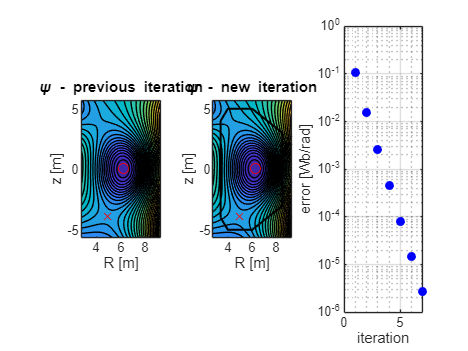

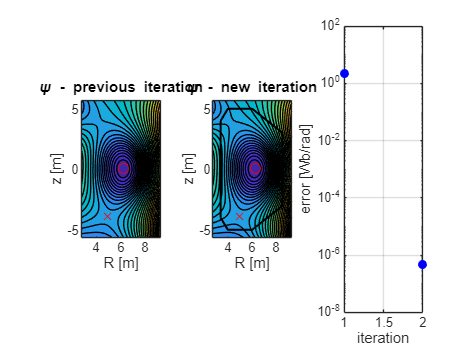

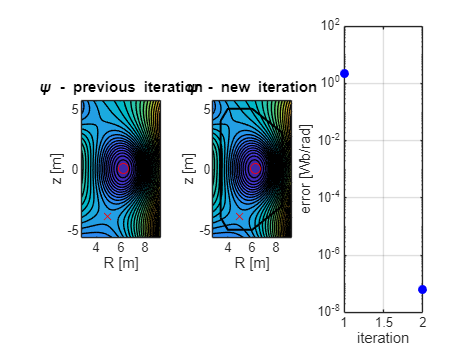

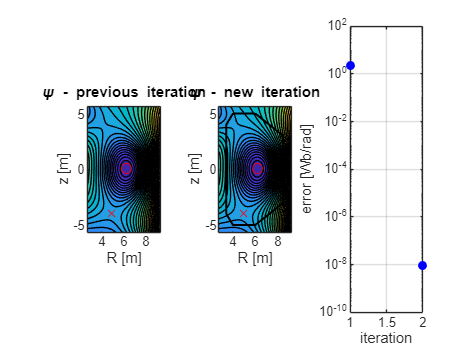

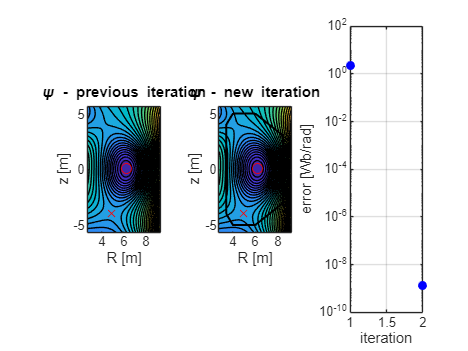

for i = 1 : N
    equi.config.toroidal_current.Ip = -Ip_s(i).*1e6;

    if i == 1
        equi = equi.solve_equilibrium();
        
    else
        equi = equi.solve_equilibrium(psi_prev);
    end
    % post processing (Opoint, Xpoint, LFCS)
    equi = equi.equi_pp();
    
    % mhd and kinetic profiles
    equi  = equi.compute_profiles();

    psi_prev = equi.psi;
    psi{i} = equi.psi;
    psi_n{i} = equi.psi_n;

end

Plot equilibrium solutions

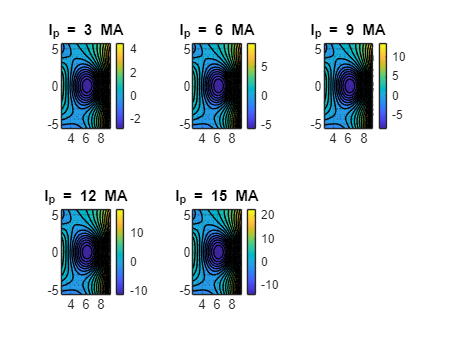

figure(1)
clf
for i = 1 : N
    
    subplot(ceil(N/3),3,i)
    contourf(equi.geo.grid.Rg,equi.geo.grid.Zg,psi{i},20)
    title("I_p = "+ num2str(Ip_s(i))+" MA")
    grid on
    grid minor
    axis equal
    colorbar()

end